# ACM 11 Least Squares Demo

## Over-determined system

In this part of the demo, we will generate *m* points from a cosine, and fit to this a polynomial of order *p*, for some *p+1<m. *Note that in this case there are more data points than degrees of freedom in the polynomial, so we cannot match all the data exactly. The degree of mismatch is measured by the norm of the residual.

clear; close all

m = 20;
data_x = linspace(0,2*pi,m)';
data_y = cos(data_x);

p = 3; % order of polynomial

% set-up LS data matrix where each row is a data point
% and each column contains the x-value raised to a 
% different power 
A = data_x.^(0:p);

% solve least squares problem using backslash!
c = A\data_y;

% show the residual norm
residual_norm = norm(A*c-data_y)

residual_norm = 0.9918

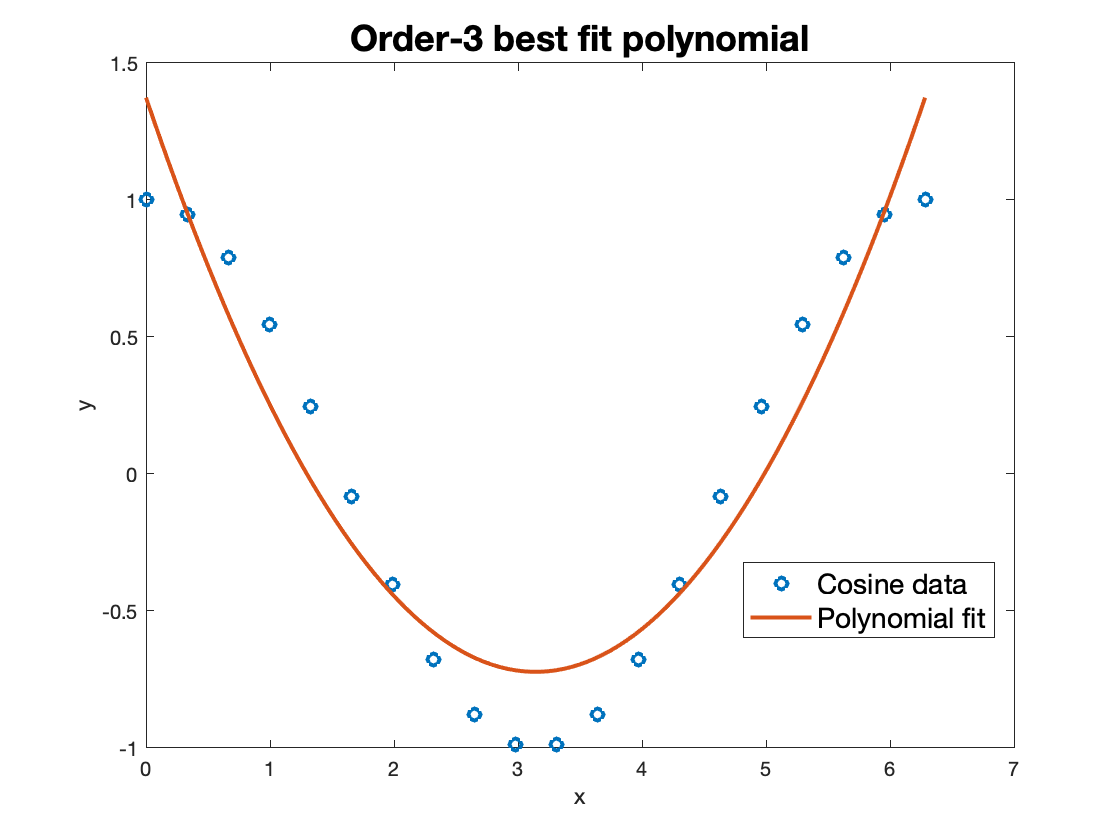


% generate some data for plotting
x_plot = linspace(0,2*pi)';
y_plot = x_plot.^(0:p)*c;

figure(1); clf
plot(data_x,data_y,'o'); hold on
plot(x_plot,y_plot)
xlabel('x')
ylabel('y')
legend('Cosine data','Polynomial fit',...
    'FontSize',14,'Location','Best')
title(['Order-',num2str(p),' best fit polynomial'],'FontSize',18)

## Under-determined system

In this example, we will look for a "line of best fit" for a single point, (2,2). Clearly, there are infinitely many solutions that pass through this point, because you need two points to uniquely define a line in two dimensions. In the code below, we can use the slider to vary the angle of the line that passes through this point (in increments of 5 degrees). In the plot title, we display the size of the coefficient vector of this line. Can you manually find the angle that leads to the smallest coefficient vector?

data_x = 2;
data_y = 2;

theta = 45

theta = 45

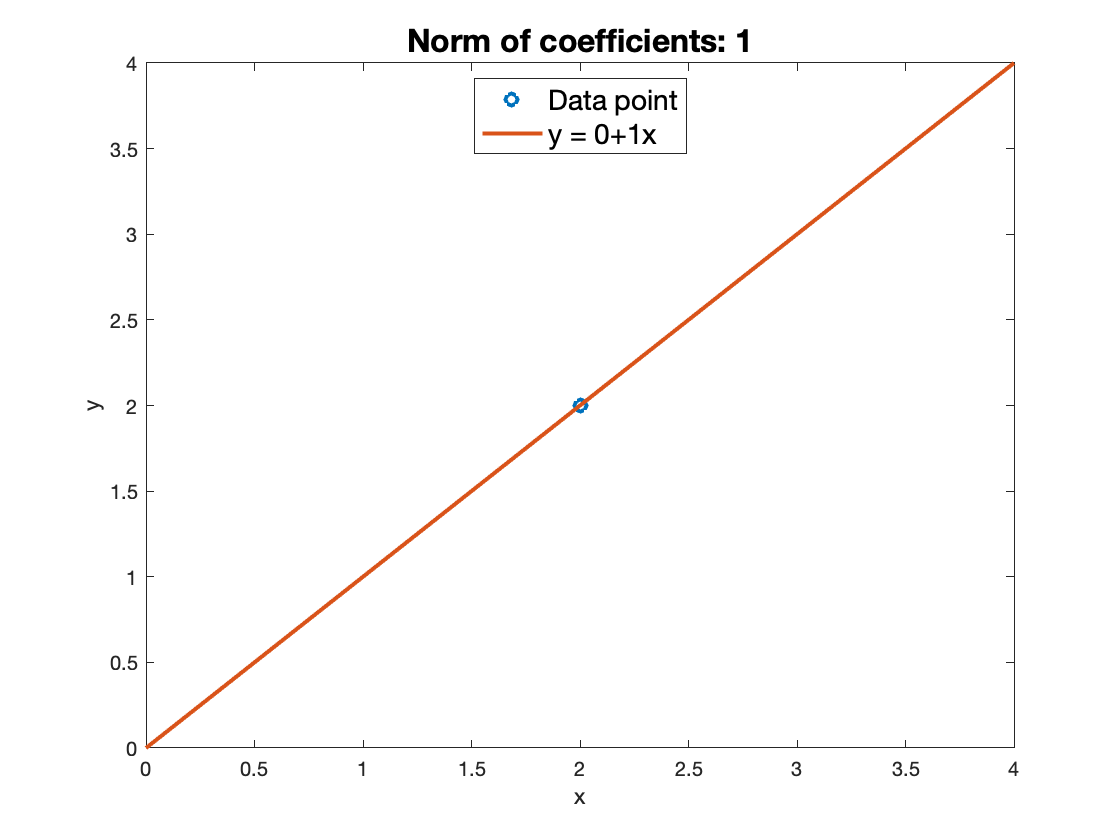

c1 = tand(theta);           % slope of line at angle theta (in degrees)
c0 = data_y - c1*data_x;    % calculate intercept

x_plot = linspace(0,4)';
y_plot = c0 + c1*x_plot;

figure(2); clf
plot(data_x,data_y,'o'); hold on
plot(x_plot,y_plot)
xlabel('x')
ylabel('y')
legend('Data point',['y = ',num2str(c0),'+',num2str(c1),'x'],'Location','North','FontSize',14)
title(['Norm of coefficients: ',num2str(norm([c0 c1]))],'FontSize',16)

MATLAB backslash automatically finds the coefficient vector of smallest norm for this under-determined system, as we see in the block below, which fits a polynomial of order 1 to our single data point.

p = 1; % order = 1 for a line

% using the single point data from above
A = data_x.^(0:p)

A =      1     2



% solve under-determined least-squares problem using backslash
c = A\data_y

c =      0
     1


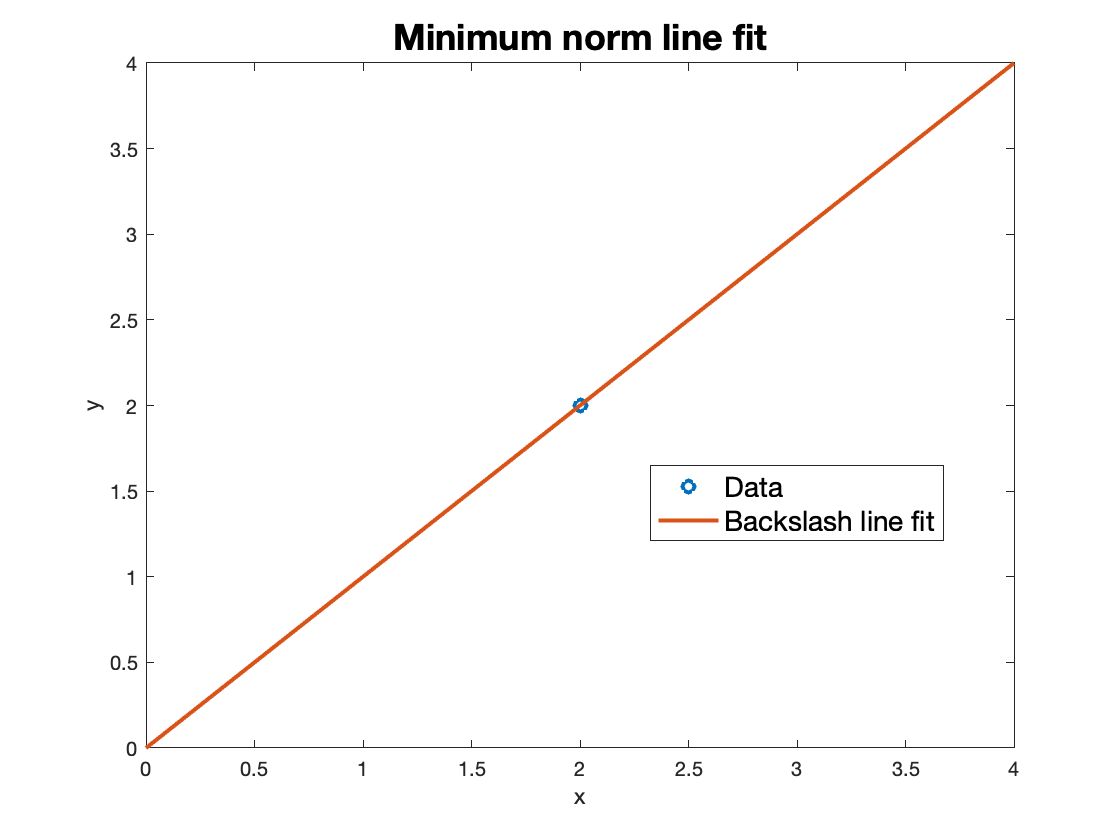


% generate some data for plotting
x_plot = linspace(0,4)';
y_plot = x_plot.^(0:p)*c;

figure(3); clf
plot(data_x,data_y,'o'); hold on
plot(x_plot,y_plot)
xlabel('x')
ylabel('y')
legend('Data','Backslash line fit',...
    'FontSize',14,'Location','Best')
title('Minimum norm line fit','FontSize',18)